# Geometrically nonlinear von Karman beam under Stochastic Excitation

Finite element model from the following reference:

 Jain, S., Tiso, P., & Haller, G. (2018). Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds. *Journal of Sound and Vibration*, *423*, 195–211. [https://doi.org/10.1016/J.JSV.2018.01.049](https://doi.org/10.1016/J.JSV.2018.01.049)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

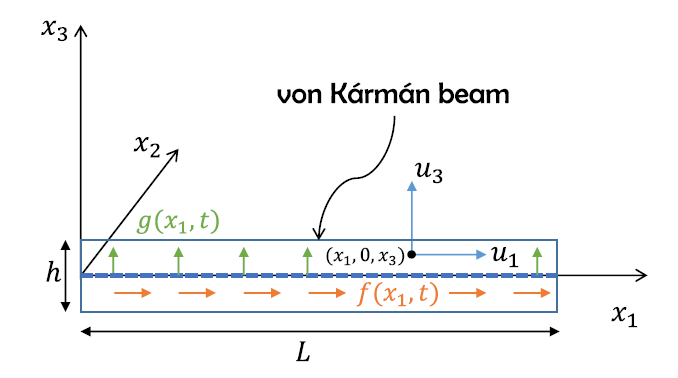

**system parameters**

nElements = 10;
epsilon = 5e-2;

## generate model

Building FE model


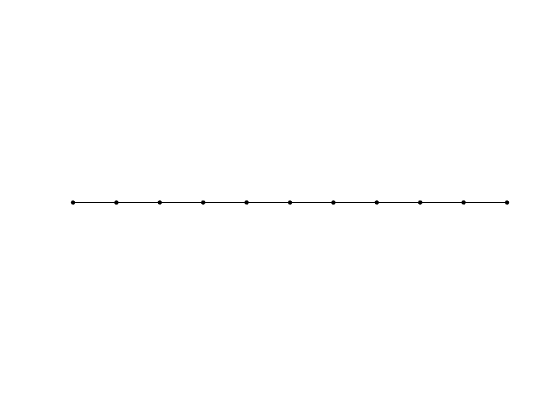

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


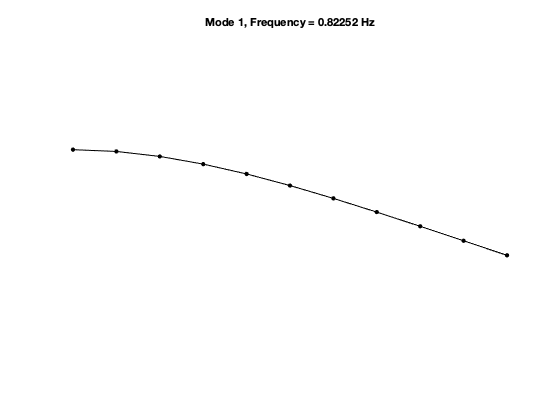

Assigning external force vector at [1   2   3   4   5   6   7   8   9  10] th element in transverse direction
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:02


[M,C,K,fnl,outdof,eMass] = build_model(nElements);

n = length(M);
nRealization=10;
resol = 2;
T0=resol*100; %% PSD frequency domain resolution is ~ 1/T0
nPoints=resol*4*2^14; %% control the accuracy of numerical differential equation

[filterPSD, stochastic_f] = build_stochasticF(eMass,n,epsilon);
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 30


## Dynamical system setup 

We consider the finite element model is under one dimensional stochastic forcing caused by the motion of the base of the cantilevered beam.


$$\mathbf{M \ddot{u}}+\mathbf{C \dot{u}}+\mathbf{K u}+\mathbf{F}_{nl}(\mathbf{u},\mathbf{\dot{u}})=\mathbf{G \ddot{u}_{G}}$$


The model with n degree-of-freedom is forced by the base movement in transverse direction ${\ddot{\mathbf{u}} }_{\mathbf{G}}$ i.e similar to seismic case and no axial motion. The mass of each element is considered and denoted as $m_1\  m_2 \ ... m_n$

The displacement vector and forcing vector are given by:

                                          
$$\mathbf{u}=[u_1\,,u_2,\,...\,u_n]\\$$


                                         
$$\mathbf{G}=[0,-m_1\,0,\ 0,-m_2,0,\,...\,\ 0,-m_n,0]$$


We assume the acceleration of the base motion ${\ddot{\mathbf{u}} }_{\mathbf{G}}$ formulated by the following 1-dimensional linear system

                                            
$$\ddot{a}(t)+c_1\dot{a}(t)+c_0(t)a(t)=I(t) \xi (t)$$


where $c_1 (t) =c_1$ , $c_0(t) =c_0
$ , $I(t) = I$ are constants and $\xi (t)$ is Gaussian white noise 

We take the velocity of $a$ to be the base acceleration:

                                                        
$$\mathbf{\dot{u}}_{G}=a \ \ \ \mathbf{\ddot{u}}_{G}=\dot{a}$$


setting for the SDE solver and allocate desired output PSD pairs

SS = StochasticSystem();    SSl = StochasticSystem();
fnl_linear = {sptensor([n,n,n]),sptensor([n,n,n,n])};
set(SS,'filterPSD',filterPSD,'linear',false)
set(SS,'M',M,'C',C,'K',K,'fnl',fnl,'gFactor',-eMass);
set(SS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
set(SS.SSOptions,'ssMethod','indirect')
SS.add_random_forcing(nRealization, T0, nPoints,outdof);
%%%%%%%%%%%%%
set(SSl,'filterPSD',filterPSD,'linear',true)
set(SSl,'M',M,'C',C,'K',K,'fnl',fnl_linear,'gFactor',-eMass);
set(SSl.Options,'Emax',5,'Nmax',10,'notation','multiindex')
set(SSl.SSOptions,'ssMethod','indirect')
SSl.add_random_forcing(nRealization, T0, nPoints,outdof);
%%%%%%%% moving linear beam(look for reference)
clusterRun=false; %% if the script is run on local or cluster.
method="filter ImplicitMidPoint";
PSDpair=[n-1,n-1];


## Linear Modal analysis ,Full System Calculation and SSM setup

[V, D, W] = SS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.691472e-03
modal damping ratio for 2 mode is 2.313481e-02
modal damping ratio for 3 mode is 6.479248e-02
modal damping ratio for 4 mode is 1.270560e-01
modal damping ratio for 5 mode is 2.103617e-01

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0002 + 0.0517i
  -0.0002 - 0.0517i
  -0.0075 + 0.3238i
  -0.0075 - 0.3238i
  -0.0588 + 0.9052i
  -0.0588 - 0.9052i
  -0.2260 + 1.7644i
  -0.2260 - 1.7644i
  -0.6195 + 2.8792i
  -0.6195 - 2.8792i



firts_res=abs(imag(D(1)));

SS.sdeImpTimeDisp = false;
[w,outputPSD] = SS.monte_carlo_average(method,PSDpair,nRealization,clusterRun);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


SSl.sdeImpTimeDisp = false;
[w_l,outputPSD_l] = SSl.monte_carlo_average(method,PSDpair,nRealization,clusterRun);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


**Choose Master subspace (perform resonance analysis)**

S = SSM(SS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);


## Power Spectral Density using SSMs

Obtaining PSD from approximation order

order = [5];  
freq_range=[4 7];
S.ssmSEulerTimeDisp = false;
[wss,ssmPSD]=S.extract_PSD(PSDpair, order,'filter heun',freq_range,clusterRun);


[w_linear, linear_analytic]=SS.compute_linear_PSD(PSDpair,freq_range);

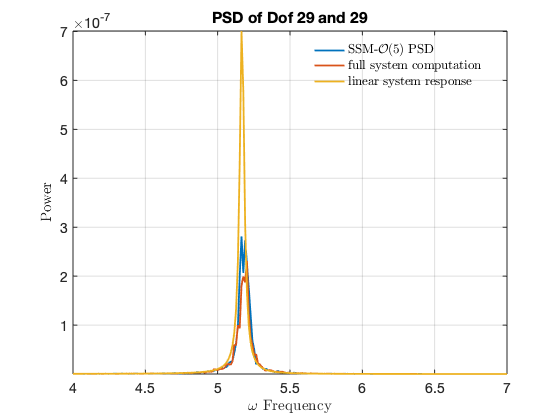

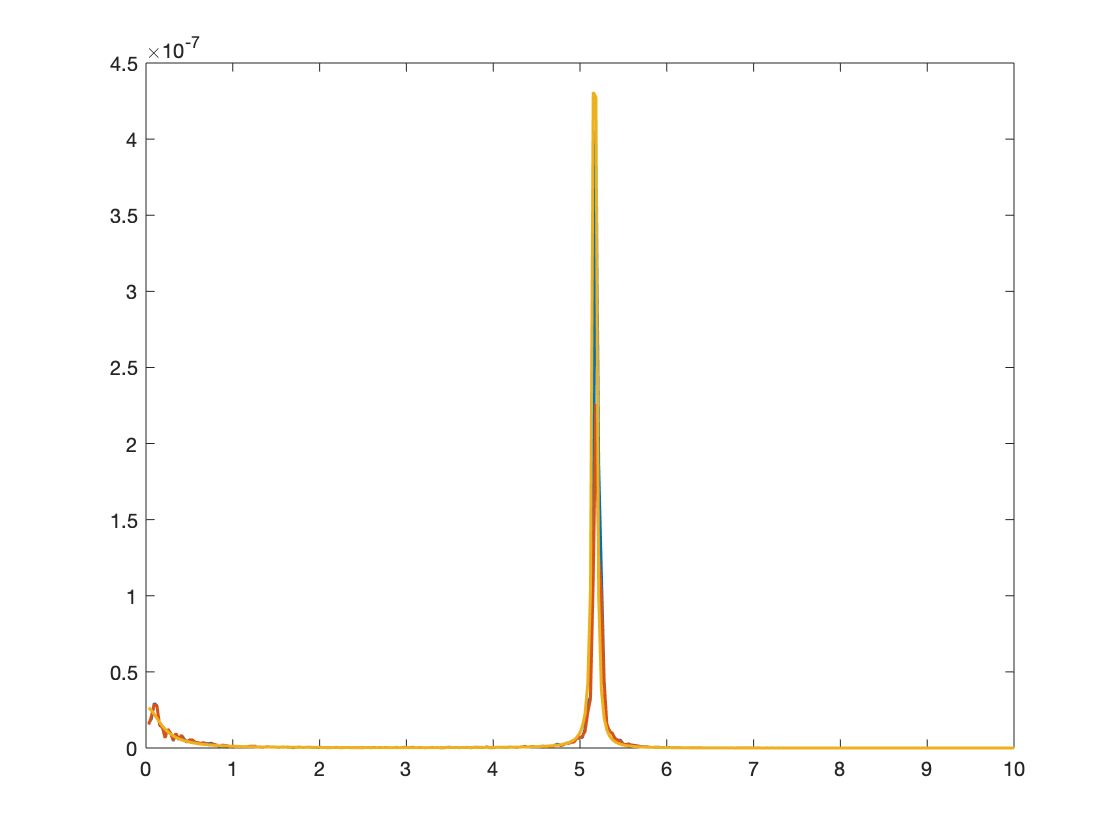

% char=['vonEpsilon',num2str(epsilon),'.mat'];
% save(char,'-mat')
plot_all_PSD(w,ssmPSD,outputPSD,linear_analytic,order,PSDpair,freq_range,true)

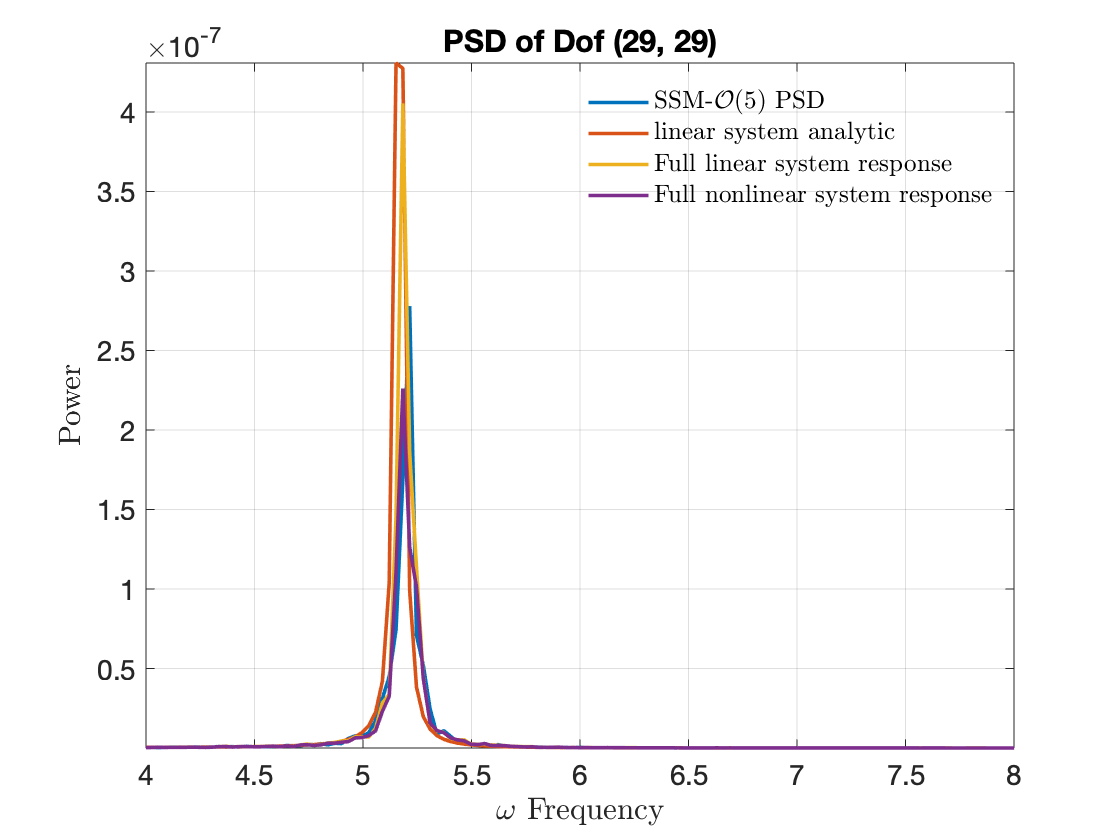

omega.linear=w_l; omega.w=wss; Gxx.Gss=ssmPSD; Gxx.linear_analytic=linear_analytic;
Gxx.full=outputPSD(1,:);  Gxx.linear_full=outputPSD_l;
plot_all_log_PSD(omega,Gxx,order,PSDpair,[4 8],true)